# Problema 4

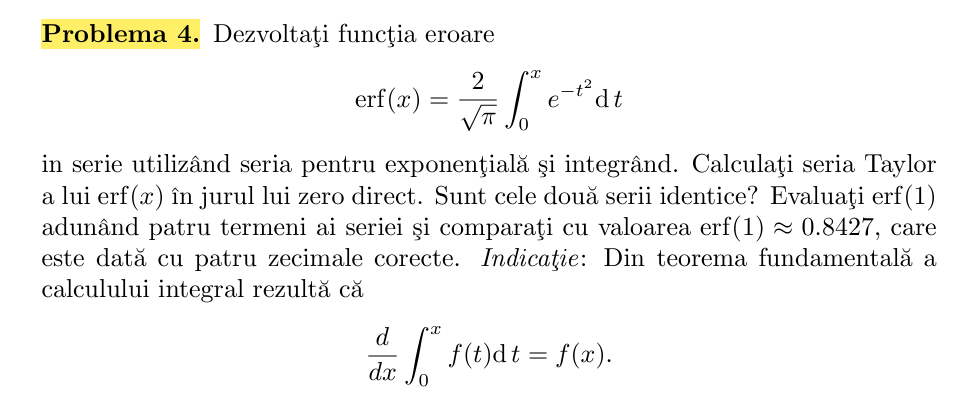

Ecuatia initiala:


$$\textrm{erf}\left(x\right)=\frac{2}{\sqrt{\pi }}\int_0^x e^{-t^2 } \;\textrm{dt}$$


Expandarea cu formula lui Taylor


$$\textrm{erf}\left(x\right)=\frac{2}{\sqrt{\pi }}\sum_{n=0}^{\infty } \frac{{\left(-1\right)}^n }{n!}\frac{x^{2n+1} }{2n+1}\;$$


COD:

syms x t n
% Seria Taylor directă pentru funcția erf(x) 
 erf_taylor = taylor(erf(x), x, 0, 'Order', 11) 

$$erf\_taylor = \frac{x^{9}}{108\,\sqrt{\pi }}-\frac{x^{7}}{21\,\sqrt{\pi }}+\frac{x^{5}}{5\,\sqrt{\pi }}-\frac{2\,x^{3}}{3\,\sqrt{\pi }}+\frac{2\,x}{\sqrt{\pi }}$$


 % Functie pentru seria taylor
function erf_approx = taylor_erf(x, N)    
    format long;
    erf_approx = 0;
    
    %Calculam suma primilor N termeni
    for n = 0:N-1
        term = (-1)^n * (x^(2*n + 1)) / ((2*n + 1) * factorial(n));
        erf_approx = erf_approx + term;
    end
    
    % Tinem cont de inmultirea cu 2/sqrt(pi)
    erf_approx = (2/sqrt(pi)) * erf_approx;
end


x = 1;
N = 4;
erf_approx = taylor_erf(x, N);
disp(['Aproximarea ', num2str(erf_approx, '%.5f')]);

Aproximarea 0.83822


disp(['Eroare ', num2str(abs(0.8427-erf_approx), '%.5f')]);

Eroare 0.00448
